# Write Foreign-Language Characters to Text Files

When your data contains foreign-language or non-ASCII characters, use the encoding parameter to ensure the file is written correctly. First, load the provided table into the workspace. Then, write the table to a file using the default encoding. Finally, write the table using `'UTF-8'` encoding and examine the result.

Load `Table_Japanese_Characters.mat` which contains a table T. A preview of the table is shown below. Notice that the table contains two columns with Japanese characters.

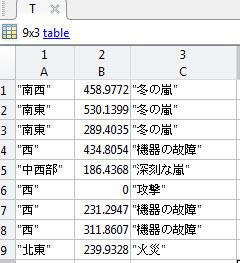

load('Table_Japanese_Characters.mat')

Write the table to a file. The `writetable` function uses your system default encoding when writing files. Results may differ based on your system settings. To examine the resulting file, read the table back into the workspace by using the `readtable` function. Notice that `writetable` did not succeed in writing columns (1 and 3) containing foreign-language characters.

writetable(T,'myTable.txt')
myTable = readtable('myTable.txt')

If your table contains foreign-language or non-ASCII characters, you must use the `'Encoding'` parameter to ensure your data is written correctly. Set `'Encoding'` to `'UTF-8'` which supports a wide range of foreign-language and non-ASCII characters. To examine the resulting file, read the table back into the workspace by using the `readtable` function. With the correct encoding parameter the `writetable` function is successful in writing the data.

writetable(T,'myTable_UTF8.txt','Encoding','UTF-8')
myTable_UTF8 = readtable('myTable_UTF8.txt','Encoding','UTF-8')

*Copyright 2012 The MathWorks, Inc.*